## read rgb and indexed img

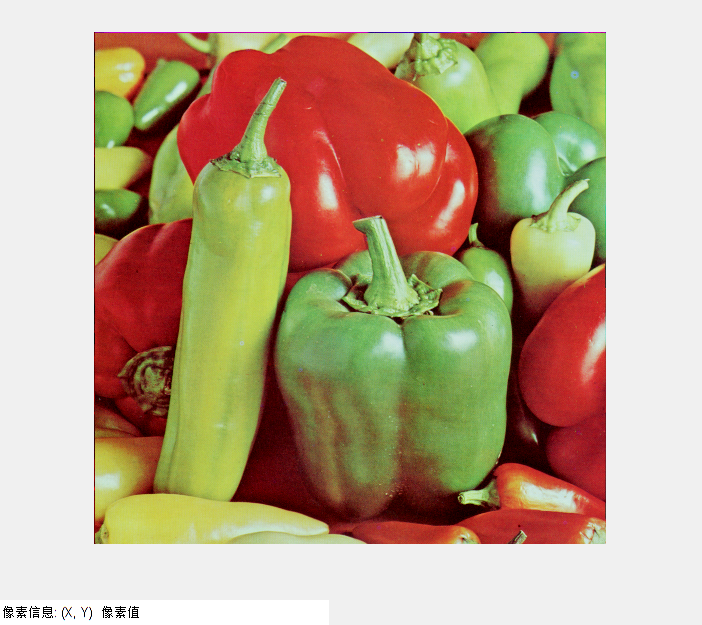

peppers = imread('peppers.tiff');
imshow(peppers)
impixelinfo

size(peppers)

ans =    512   512     3


impixel(peppers, 300, 400)

ans =    135   131    77


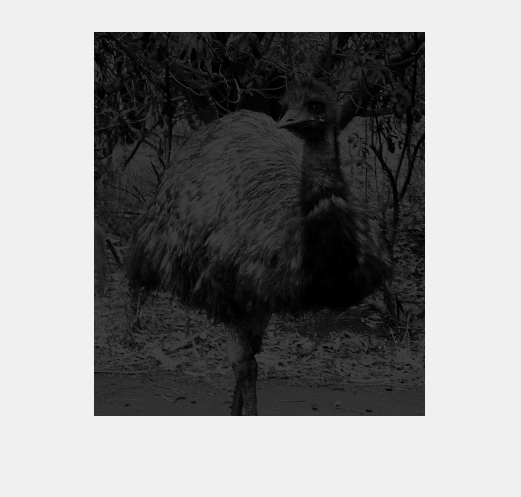

img_emu = imread('emu.tif');
imshow(img_emu)

imfinfo('emu.tif')

ans = 包含以下字段的 struct :
                     Filename: 'F:\spectral_demo\mat_demo\learning\emu.tif'
                  FileModDate: '03-6月-2021 15:03:33'
                     FileSize: 119804
                       Format: 'tif'
                FormatVersion: []
                        Width: 331
                       Height: 384
                     BitDepth: 8
                    ColorType: 'indexed'
              FormatSignature: [73 73 42 0]
                    ByteOrder: 'little-endian'
               NewSubFileType: 0
                BitsPerSample: 8
                  Compression: 'PackBits'
    PhotometricInterpretation: 'RGB Palette'
                 StripOffsets: [8 7831 15512 23032 30418 38104 45851 53514 61066 68460 75620 82394 89310 96928 104654 111918]
              SamplesPerPixel: 1
                 RowsPerStrip: 24
              StripByteCounts: [7823 7681 7520 7386 7686 7747 7663 7552 7394 7160 6774 6916 7618 7726 7264 6020]
                  XResolution: 72
           

[emu, emu_map] = imread('emu.tif')

emu = 384×331 uint8 矩阵
   15   16   15   16   20   16   20   19   19   28   37   28   11    4   13   14   31   23   24   16   16   16   16   19   16   19   28   35   35   19   16   26   37   38   23   12   35   43    9   17   25   27   17   46   46   32   36   34   32   17
   26   28   37   37   37   28   19   26   28   37   37   28   16    8    4    9   14   22   23   16   19   16   16   19   19   26   37   28   24   28   28   37   43   23   16   12    9   43   30   18   25   25   25   25   46   46   25   32   25   17
   16   20   16   16   20   37   45   37   28   30   28   28   28   19    4    4    8   14   20   23   19   16   16   19   28   28   28   19   19   28   43   43   28   12   10   12   10   16   51   36   23   25   32   27   32   46   39   25   27    9
   11    8   11   16   37   28   19   12    4    4    4   11   11   12   11    4    4    8   14   19   28   24   19   19   37   35   16   19   38   43   38   19   12   10    2   10   10   23   23   51   27   25   31   27   3

emu_map =     0.1211    0.1211    0.1416
    0.1807    0.2549    0.1729
    0.2197    0.3447    0.1807
    0.1611    0.1768    0.1924
    0.2432    0.2471    0.1924
    0.2119    0.1963    0.2002
    0.2627    0.2588    0.2549
    0.2197    0.2432    0.2588
    0.2939    0.2822    0.2627
    0.2471    0.3604    0.2627


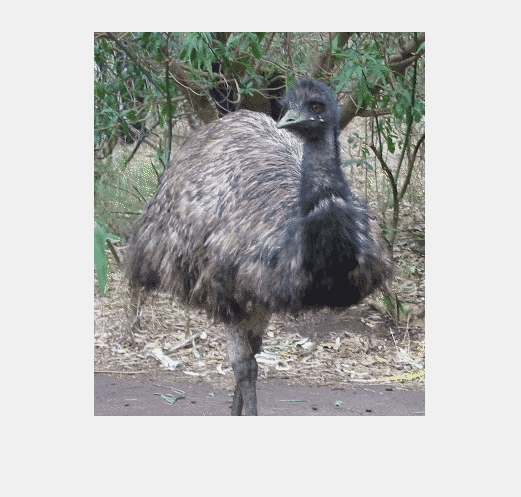

imshow(emu, emu_map)

## format conversion

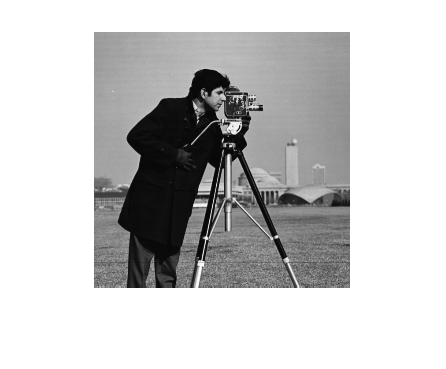

cameraman = imread('cameraman.tif');
figure, imshow(cameraman)

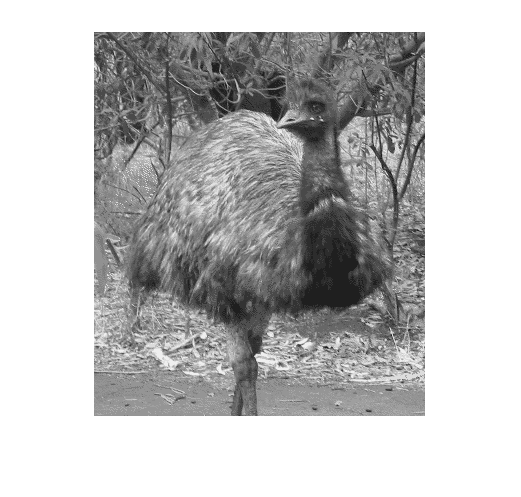

emu_gray = ind2gray(emu, emu_map);
imshow(emu_gray)